QVec = []


QVec =

     []



for n = [ .01 .0138 .02]
L = 2000; %length of channel, meters (m)
b = 5;  %width of the bottom of the channel, meters (m)
S0 = .0005  %slope of the bottom of the channel
 %Manning's roughness coefficient for the bottom of the channel
g = 9.8; %acceleration due to gravity, m^2/s
h = 3.5; %water depth, meters (m)

%set up time and space vectors
dt = 0.61; % delta t, seconds (s)
t = 0:dt:50; %time vector
dx = 100; % delta a, meters (m)
x = 0:dx:L; %space vector

%pre-allocate Q matrix and A matrix
%Discharge (Q) matrix:
Q = zeros(length(x), length(t));
%set up boundary conditions for Q
Q0 = 3; %base flow of inflow hydrograph in m^3/s
Qp = 12; %peak flow of inflow hydrograph in m^3/s
tp = 10;
tb = 20;
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;

% Cross Section Area (A) matrix:
A = ones(length(x), length(t));
A(:,1) = b*h;

%matrix with the same dimensions to keep track of Courant value
C = zeros(length(x), length(t));

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 

        R = A(i,j)/(2*h+b); %R is the hydraulic radius
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
        
        C(i,j) = (dt/dx) * alpha; %need to keep this below 1 to remain stable

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + (beta)*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j+1)-Q(i-1,j+1));
    end
end

QVec = [ QVec ;Q(6,:)]


end

S0 = 5.0000e-04

QVec =     3.0000    2.9509    2.9018    2.8525    2.8032    2.7537    3.3269    3.5177    3.7978    4.0843    4.3727    4.6626    4.9539    5.2467    5.5411    5.8371    6.1349    6.4346    6.7362    7.0399    7.3457    7.6538    7.9614    8.2627    8.5500    8.8153    9.0514    9.2514    9.4089    9.5177    9.5715    9.5636    9.4864    9.3309    9.0857    8.7360    8.2606    7.6274    6.7871    5.7086    4.4778    3.4006    2.8451    2.7529    2.7553    2.7552    2.7552    2.7552    2.7552    2.7552


S0 = 5.0000e-04

QVec =     3.0000    2.9509    2.9018    2.8525    2.8032    2.7537    3.3269    3.5177    3.7978    4.0843    4.3727    4.6626    4.9539    5.2467    5.5411    5.8371    6.1349    6.4346    6.7362    7.0399    7.3457    7.6538    7.9614    8.2627    8.5500    8.8153    9.0514    9.2514    9.4089    9.5177    9.5715    9.5636    9.4864    9.3309    9.0857    8.7360    8.2606    7.6274    6.7871    5.7086    4.4778    3.4006    2.8451    2.7529    2.7553    2.7552    2.7552    2.7552    2.7552    2.7552
    3.0000    2.9539    2.9076    2.8611    2.8144    2.7676    3.3310    3.5326    3.8166    4.1077    4.4016    4.6977    4.9961    5.2969    5.6004    5.9066    6.2157    6.5279    6.8434    7.1624    7.4850    7.8115    8.1395    8.4634    8.7761    9.0696    9.3368    9.5704    9.7638    9.9103   10.0030   10.0344    9.9962    9.8787    9.6698    9.3539    8.9097    8.3053    7.4929    6.4328    5.1676    3.9216    3.0703    2.7836    2.7670    2.7678    2.7677    2.7677    2.7677  

S0 = 5.0000e-04

QVec =     3.0000    2.9509    2.9018    2.8525    2.8032    2.7537    3.3269    3.5177    3.7978    4.0843    4.3727    4.6626    4.9539    5.2467    5.5411    5.8371    6.1349    6.4346    6.7362    7.0399    7.3457    7.6538    7.9614    8.2627    8.5500    8.8153    9.0514    9.2514    9.4089    9.5177    9.5715    9.5636    9.4864    9.3309    9.0857    8.7360    8.2606    7.6274    6.7871    5.7086    4.4778    3.4006    2.8451    2.7529    2.7553    2.7552    2.7552    2.7552    2.7552    2.7552
    3.0000    2.9539    2.9076    2.8611    2.8144    2.7676    3.3310    3.5326    3.8166    4.1077    4.4016    4.6977    4.9961    5.2969    5.6004    5.9066    6.2157    6.5279    6.8434    7.1624    7.4850    7.8115    8.1395    8.4634    8.7761    9.0696    9.3368    9.5704    9.7638    9.9103   10.0030   10.0344    9.9962    9.8787    9.6698    9.3539    8.9097    8.3053    7.4929    6.4328    5.1676    3.9216    3.0703    2.7836    2.7670    2.7678    2.7677    2.7677    2.7677  

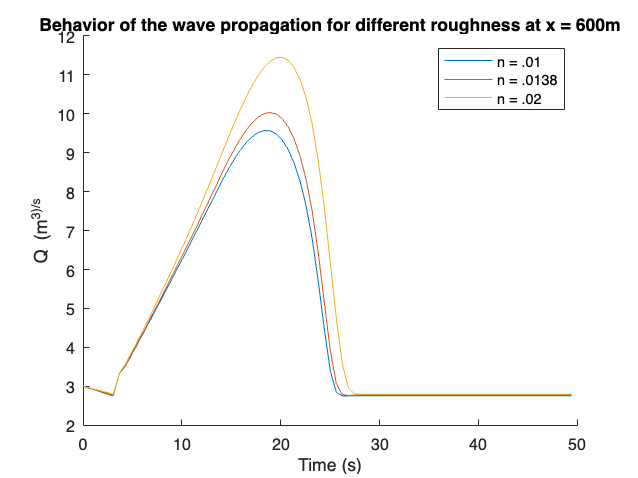


figure 
hold on
plot(t, QVec(1,:))
plot(t, QVec(2,:))
plot(t, QVec(3,:))
xlabel('Time (s)')
ylabel('Q (m^3)/s')
title('Behavior of the wave propagation for different roughness at x = 600m')
legend('n = .01', 'n = .0138', 'n = .02')